# Problem 3

clc;
clear;
close all;

## Part A

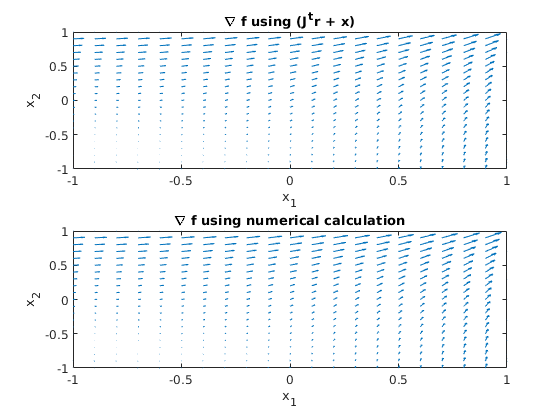

% Generate function, gradient, and hessian for example domain
step = 1e-1;
x = -1:step:1;
y = -1:step:1;
[xx, yy] = meshgrid(x,y);
nx = numel(x);
ny = numel(y);
f = zeros(nx,ny);
g = zeros(nx,ny,2);
H = zeros(nx,ny,2,2);
for i=1:nx
    for j=1:ny
        [f(i,j),g(i,j,:),H(i,j,:,:)] = objectiveFunction([x(i);y(j)]);
    end
end

% numerically calculate gradient
[gy, gx] = gradient(f,step);

% plot gradient
figure;
subplot(211); quiver(xx,yy,g(:,:,1),g(:,:,2));
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}'); 
title('\nabla f using (J^{t}r + x)')
subplot(212); quiver(xx,yy,gx,gy);
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}');
title('\nabla f using numerical calculation')

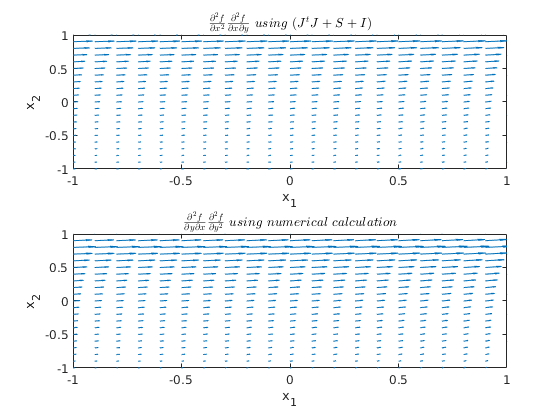

% numerically calculate hessian
[gyy,gyx] = gradient(gy,step);
[gxy,gxx] = gradient(gx,step);

% plot top row hessian
figure;
subplot(211); quiver(xx,yy,H(:,:,1,1),H(:,:,1,2));
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}');
title('$\frac{\partial^{2} f}{\partial x^{2}} \frac{\partial^{2} f}{\partial x \partial y} \ using \ (J^{t} J + S + I)$','Interpreter','latex');
subplot(212); quiver(xx,yy,gxx,gxy);
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}');
title('$\frac{\partial^{2} f}{\partial y \partial x} \frac{\partial^{2} f}{\partial y^{2}} \ using \ numerical \ calculation$','Interpreter','latex');

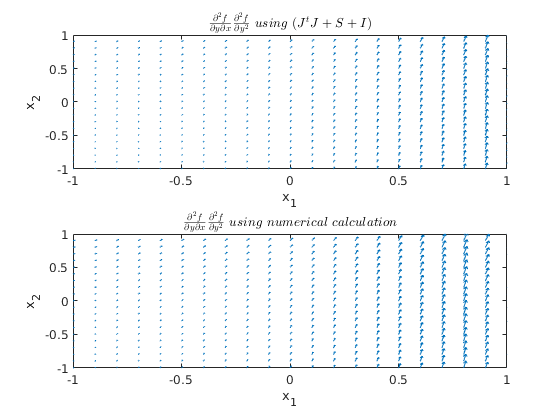

% plot bottom row hessian
figure;
subplot(211); quiver(xx,yy,H(:,:,2,1),H(:,:,2,2));
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}');
title('$\frac{\partial^{2} f}{\partial y \partial x} \frac{\partial^{2} f}{\partial y^{2}} \ using \ (J^{t} J + S + I)$','Interpreter','latex');
subplot(212); quiver(xx,yy,gyx,gyy);
xlim([-1,1]); ylim([-1,1]); xlabel('x_{1}'); ylabel('x_{2}');
title('$\frac{\partial^{2} f}{\partial y \partial x} \frac{\partial^{2} f}{\partial y^{2}} \ using \ numerical \ calculation$','Interpreter','latex');

## Part B

For the 2nd and 3rd options for $\eta$, the number of iterations give much faster convergence than the 1st option for $\eta$.

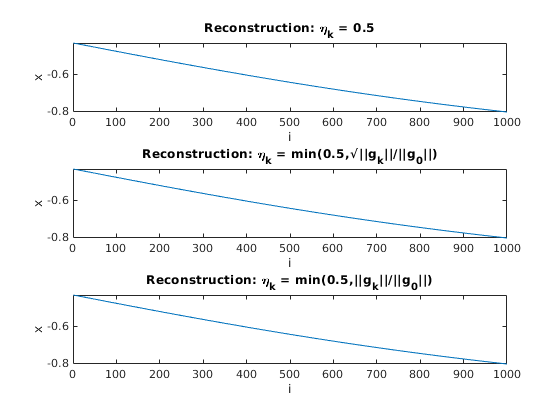

% define different eta functions
eta1 = @(g,g0) 0.5;
eta2 = @(g,g0) min([0.5, sqrt(norm(g)/norm(g0))]);
eta3 = @(g,g0) min([0.5, norm(g)/norm(g0)]);

% do inexact cg
[x1, g1] = inexact_cg(eta1,1000,20);
[x2, g2] = inexact_cg(eta2,1000,20);
[x3, g3] = inexact_cg(eta3,1000,20);

% plot recon
figure;
subplot(311); plot(x1); xlabel('i'); ylabel('x');
title('Reconstruction: \eta_{k} = 0.5');
subplot(312); plot(x2); xlabel('i'); ylabel('x');
title('Reconstruction: \eta_{k} = min(0.5,\surd||g_{k}||/||g_{0}||)');
subplot(313); plot(x3); xlabel('i'); ylabel('x');
title('Reconstruction: \eta_{k} = min(0.5,||g_{k}||/||g_{0}||)');

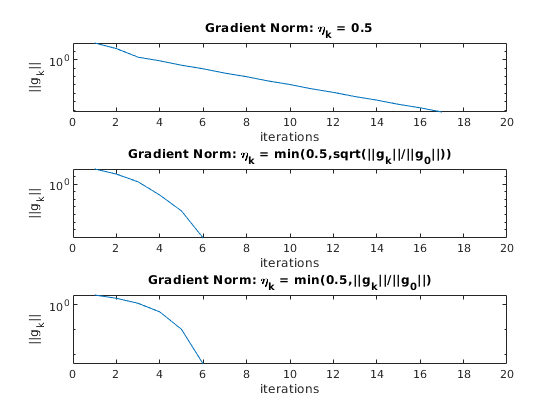

% plot norm of gradient over iterations
figure;
subplot(311); semilogy(g1); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: \eta_{k} = 0.5'); xlim([0,20]);
subplot(312); semilogy(g2); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: \eta_{k} = min(0.5,sqrt(||g_{k}||/||g_{0}||))'); xlim([0,20]);
subplot(313); semilogy(g3); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: \eta_{k} = min(0.5,||g_{k}||/||g_{0}||)'); xlim([0,20]);

## Part C

Even for increasing n, we can see that the convergence rate of Newton-CG remains constant.

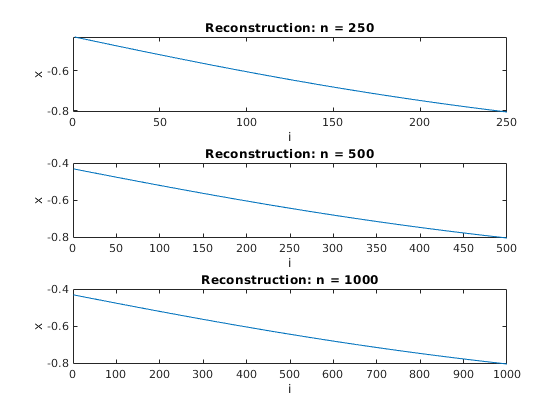

% do inexact cg for different n
[xn1, gn1, cgs1] = inexact_cg(eta3,250,10);
[xn2, gn2, cgs2] = inexact_cg(eta3,500,10);
[xn3, gn3, cgs3] = inexact_cg(eta3,1000,10);

% plot recon
figure;
subplot(311); plot(xn1); xlabel('i'); ylabel('x');
title('Reconstruction: n = 250');
subplot(312); plot(xn2); xlabel('i'); ylabel('x');
title('Reconstruction: n = 500');
subplot(313); plot(xn3); xlabel('i'); ylabel('x');
title('Reconstruction: n = 1000');

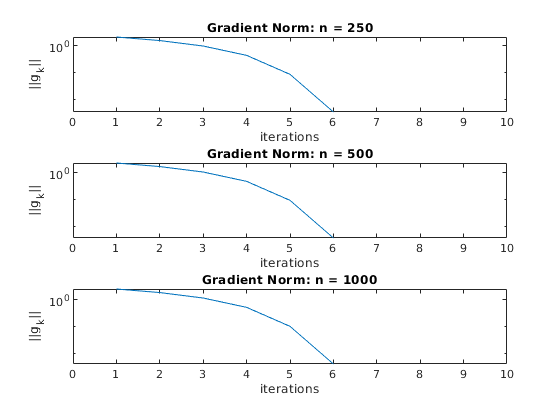

% plot norm of gradient over iterations
figure;
subplot(311); semilogy(gn1); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: n = 250'); xlim([0,10]);
subplot(312); semilogy(gn2); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: n = 500'); xlim([0,10]);
subplot(313); semilogy(gn3); xlabel('iterations'); ylabel('||g_{k}||');
title('Gradient Norm: n = 1000'); xlim([0,10]);

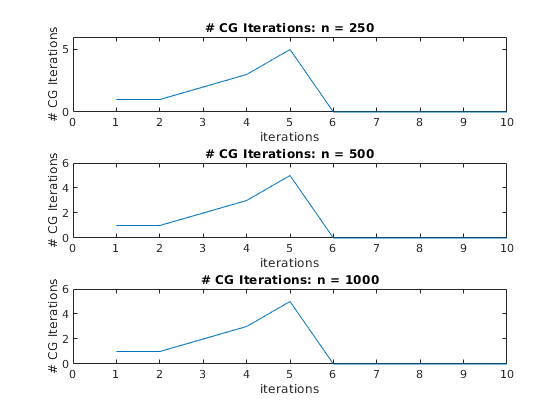

% plot cgs iterations
figure;
subplot(311); plot(cgs1); xlabel('iterations'); ylabel('# CG Iterations');
title('# CG Iterations: n = 250'); xlim([0,10]); ylim([0,6]);
subplot(312); plot(cgs2); xlabel('iterations'); ylabel('# CG Iterations');
title('# CG Iterations: n = 500'); xlim([0,10]); ylim([0,6]);
subplot(313); plot(cgs3); xlabel('iterations'); ylabel('# CG Iterations');
title('# CG Iterations: n = 1000'); xlim([0,10]); ylim([0,6]);

function [x, gnorm, cgs] = inexact_cg(eta,n,iterations)
    % common settings
    backtrack_iter = 100;
    rtol = 10^-8;
    c = 1e-5;
    
    % set initial x and pk
    x = zeros(n,1);
    g = zeros(n,iterations);
    gnorm = zeros(iterations,1);
    cgs = zeros(iterations,1);
    
    for i=1:iterations
        % Get f,g and h
        [f,g(:,i),H] = objectiveFunction(x);
        
        % store gradient norm
        gnorm(i) = norm(g(:,i));
        
        % save initital gradient
        if i == 1
           g0 = g(:,i); 
        end
        
        % break if <= tolerance
        if norm(g(:,i))/norm(g0) <= rtol
            break;
        end
        
        % get pk using cg_steihaug
        [pk, cgs(i)] = cg_steihaug(H,-g(:,i),1000,eta(g(:,i),g0),zeros(n,1));
        
        % do armijo backtracking
        alpha = 1;
        for j=1:backtrack_iter
            [fprop,~,~] = objectiveFunction(x+alpha*pk);
            if fprop <= f + c*alpha*g(:,i)'*pk
                break;
            else
                alpha = alpha/2;
            end
        end
        
        % update x
        x = x + alpha*pk;
    end
end